## Setup the Virtual Simulation Environment

[**Instructions to setup RoboCup ARM provided virtual machine**](https://drive.google.com/file/d/1w9tBy3DKmZBKEfOqOFUXcT8hcQig6sNS/view)** (Appendix A)**

Follow the instructions above to setup the MathWorks provided Virtual Machine in your computer.

Find and open one of the environments for the RoboCup ARM Challenge. Note that there is more than on environment provided to ilustrate how objects in the environments are subject to changing positions and orientations based on the challenge instructions. 

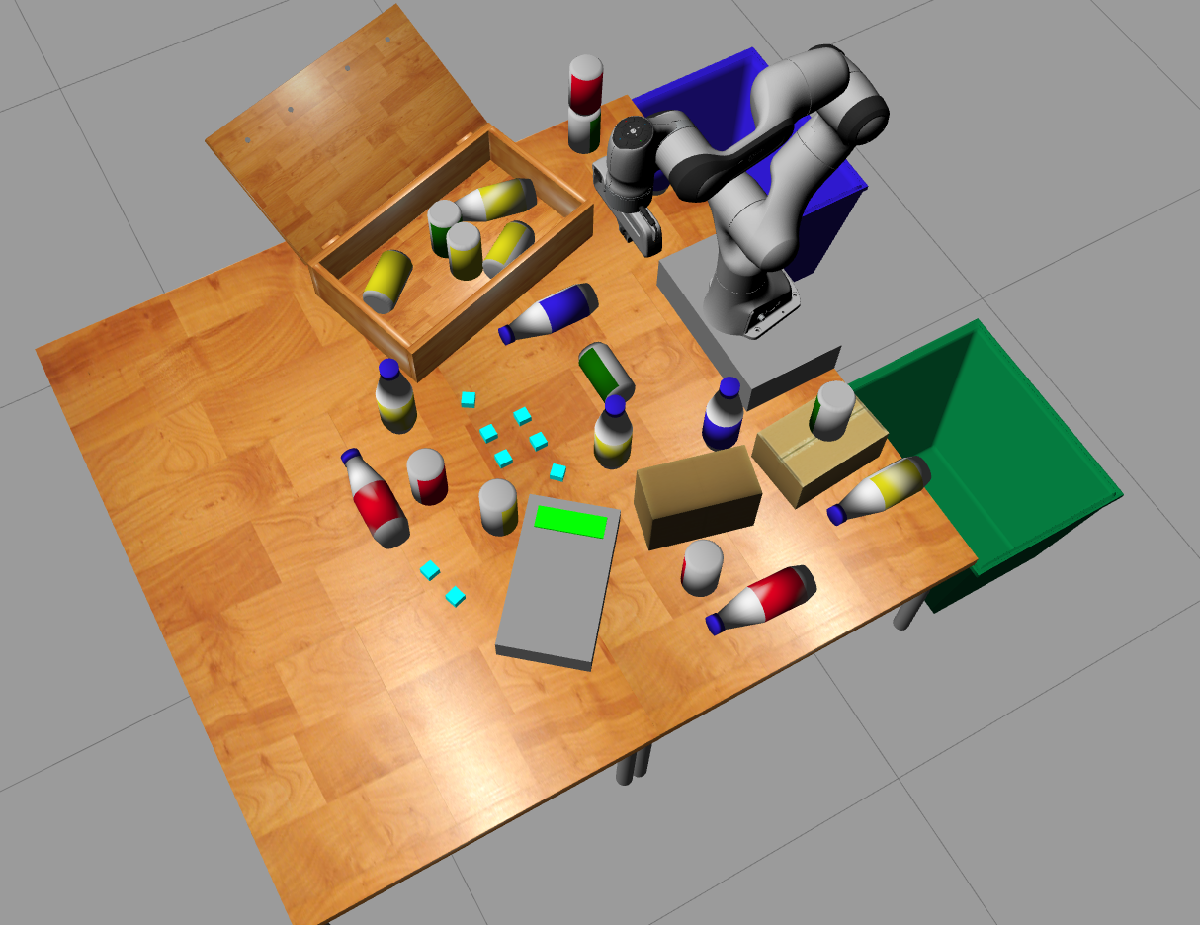

#### Connect MATLAB to Gazebo using the ROS Toolbox

Start a ROS node from MATLAB to interact with the Gazebo environment. For more information on interaction with the ROS ecosystem from MATLAB visit [Getting Started with ROS Toolbox](https://www.mathworks.com/help/ros/getting-started-with-ros-toolbox.html).

If you are having trouble with this step, or if you are waiting a long time for the nodes to communicate, try using the commented code in line 4. The IP address to be specified is the wireless network adapter address.

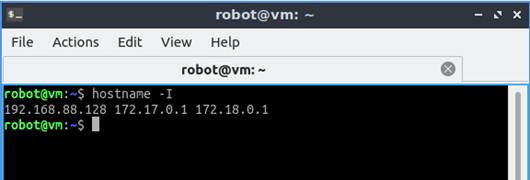

rosIP = "192.168.42.128"; % Change IP address!!    % IP address of ROS enabled machine  
rosshutdown; % shut down existing connection to ROS

Shutting down global node /matlab_global_node_60422 with NodeURI http://192.168.42.1:50252/ and MasterURI http://192.168.42.128:11311.


rosinit(rosIP,11311);

Initializing global node /matlab_global_node_28930 with NodeURI http://192.168.42.1:50263/ and MasterURI http://192.168.42.128:11311.


% rosinit(rosIP,'NodeHost','192.168.68.120') % Try specifying node host IP in case that there are multiple network adapters

## Initialize Robot and Start Simulator

#### Set initial robot configuration

setInitialConfig_franka; % DO NOT MODIFY

#### Unpause GAZEBO physics.

Unpausing the Gazebo simulation is necessary to make sure the environment physics are active.

physicsClient = rossvcclient('gazebo/unpause_physics'); %unpause physics
physicsResp = call(physicsClient,'Timeout',3); %send default message

## Control Gripper Using ROS Action Client

[gripAct,gripGoal] = rosactionclient('/franka_gripper/gripper_action');
gripperCommand = rosmessage(gripAct);

## Control Gripper Position using ROS Action Client

#### Setup ROS message and publisher for Joint Control

jointMess = rosmessage("geometry_msgs/PoseStamped");
jointPub = rospublisher("/cartesian_impedance_example_controller/equilibrium_pose");
pause(2);

**Abrir o cerrar Gripper**

gripperCommand.Command.Position = 4; %0 is fully closed, 4 is fully open
gripperCommand.Command.MaxEffort = 50; %N
gripperCommand.Command.Position = gripperCommand.Command.Position / 100;
gripGoal.Command = gripperCommand.Command;
% waitForServer(gripAct); % Can use this function if concerned with missed
% goals but generally it should work correctly.
sendGoal(gripAct,gripGoal)

#### Define Gripper Pose

This section defines the desired gripper location and orientation using a homogeneous transformation. [Learn more about homogeneous transform here.](https://www.mathworks.com/help/robotics/coordinate-system-transformations.html)

To reset pose to approximate initial configuration, set the gripper location to [0.35, 0.0001, 0.5] and orientation to [-pi. -0.01,0]

gripperX = 0.42;
gripperY = 0.07;
gripperZ = 0.4;

gripperTranslation = [gripperX gripperY gripperZ];
gripperRotationX = -pi; % radians
gripperRotationY = -0.01; % radians
gripperRotationZ = 0; % radians

jointMess.Pose.Position.X = gripperX;
jointMess.Pose.Position.Y = gripperY;
jointMess.Pose.Position.Z = gripperZ;
quat = angle2quat(gripperRotationX, gripperRotationY, gripperRotationZ, "XYZ");
jointMess.Pose.Orientation.W = quat(1);
jointMess.Pose.Orientation.X = quat(2);
jointMess.Pose.Orientation.Y = quat(3);
jointMess.Pose.Orientation.Z = quat(4);
send(jointPub,jointMess);

%Obtener información de la velocidad de las joints en info.Velocity
% sub = rossubscriber('/franka_state_controller/joint_states_desired')
% pause(0.5)
% info1 = receive(sub,3)
% pause(10)
% info2 = receive(sub,3)

**Get image **

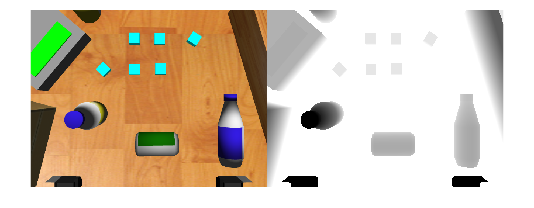

rgbImgSub = rossubscriber("/camera/rgb/image_raw","sensor_msgs/Image","DataFormat","struct");
curImage = receive(rgbImgSub,3);
pause(1)
rgbImg = rosReadImage(rgbImgSub.LatestMessage); 
rgbDptSub = rossubscriber('/camera/depth/image_raw');
curDepth = receive(rgbDptSub,3);
depthImg = readImage(rgbDptSub.LatestMessage); 
imshowpair(rgbImg,depthImg,"montage")

DptPoint = rossubscriber('/camera/depth/points')

DptPoint =   Subscriber with properties:

        TopicName: '/camera/depth/points'
    LatestMessage: [0×1 PointCloud2]
      MessageType: 'sensor_msgs/PointCloud2'
       BufferSize: 1
    NewMessageFcn: []
       DataFormat: 'object'


pointDepth = receive(DptPoint,3)

pointDepth =   ROS PointCloud2 message with properties:

    PreserveStructureOnRead: 0
                MessageType: 'sensor_msgs/PointCloud2'
                     Header: [1×1 Header]
                     Fields: [4×1 PointField]
                     Height: 480
                      Width: 640
                IsBigendian: 0
                  PointStep: 32
                    RowStep: 20480
                       Data: [9830400×1 uint8]
                    IsDense: 0

  Use showdetails to show the contents of the message


xyz2 = readXYZ(pointDepth)

xyz2 = 307200×3 single matrix
   -0.3135   -0.2350    0.5439
   -0.3125   -0.2350    0.5439
   -0.3115   -0.2350    0.5439
   -0.3105   -0.2350    0.5439
   -0.3095   -0.2350    0.5439
   -0.3085   -0.2350    0.5439
   -0.3076   -0.2350    0.5439
   -0.3066   -0.2350    0.5439
   -0.3056   -0.2350    0.5439
   -0.3046   -0.2350    0.5439


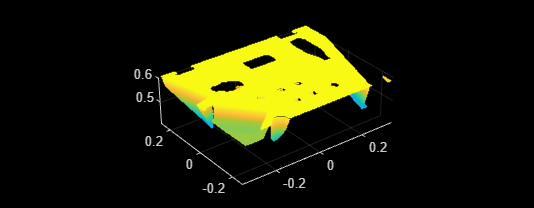

pcshow(xyz2)

## Rutina para objetos estáticos

**Rutina para botella azul**

rx = -pi;
ry = -0.01;
rz = 0;

%Posición de inicio
MoveGripper(-0.38,-0.5,0.2,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(2)

%Abrir gripper
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(4)

%Posición antes de agarrar botella azul
MoveGripper(-0.07,-0.52,0.2,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



%wait
pause(3)

%Posición para agarrar botella azul
MoveGripper(-0.07,-0.46,0.08,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Tomar botella azul
OpenGripper(2,15,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(4)

%Posición después de agarrar botella azul
MoveGripper(-0.08,-0.5,0.2,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Posición para tirar la botella azul
MoveGripper(-0.38,-0.5,0.2,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Soltar botella azul
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

ans = logical
   1


**Rutina botella amarilla**

rx = -pi;
ry = -0.01;
rz = 0;

%Posición inicio
MoveGripper(0.4,0,0.3,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(6)

%Posición para acercarse a la botella amarilla
MoveGripper(0.04,0.53,0.2,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)

%Posición para orillar la caja
MoveGripper(0.1,0.6,-0.06,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)

%Posición para orillar la caja
MoveGripper(0.1,0.45,-0.06,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Posición para acercarse a la botella amarilla
MoveGripper(0.04,0.53,0.05,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Abri gripper
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(5)

%Posición para tomar a la botella amarilla
MoveGripper(0.042,0.53,-0.07,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(5)

%Cerrar gripper
OpenGripper(2,15,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(3)

%Posición para subir la botella amarilla
MoveGripper(0.04,0.53,0.35,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Posición en camino al bote
MoveGripper(0.4,0,0.35,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Posición para tirar la botella azul
MoveGripper(-0.33,-0.5,0.2,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Abrir gripper
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(3)

**Rutina para botella roja**

rx = -pi;
ry = -0.01;
rz = 0;

%Posición inicio
MoveGripper(0.4,0,0.3,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)

%Abrir gripper
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(4)

%Posición para acercarse a la botella roja
MoveGripper(0.4,0.63,0.3,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)

rx = -pi;
ry = -0.01;
rz = -pi/2;

%Posición para acercarse a la botella roja
MoveGripper(0.25,0.52,0.3,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(6)

%Posición para empujar a la lata roja
MoveGripper(0.25,0.52,-0.07,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Posición para empujar a la lata roja
MoveGripper(0.35,0.52,-0.07,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)

%Posición para acercarme a la botella roja
MoveGripper(0.35,0.52,0.03,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)

rx = -pi;
ry = -0.01;
rz = 0;

%Posición para acercarme a la botella roja
MoveGripper(0.35,0.63,0.03,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(6)

%Posición para acercarme a la botella roja
MoveGripper(0.4,0.625,-0.02,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Abri gripper
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(3)

%Posición para tomar a la botella roja
MoveGripper(0.42,0.625,-0.07,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Cerrar gripper
OpenGripper(2,15,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(3)

%Posición para tomar a la botella roja
MoveGripper(0.42,0.625,0.3,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Posición en camino al bote
MoveGripper(0.4,0,0.3,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Posición para tirar la botella azul
MoveGripper(-0.33,-0.5,0.2,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3)

%Abrir gripper
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(3)

**Rutina cubos**

%Posición inicio
x = 0.826;
y = -0.033;
z = 0.3;
rx = -pi;
ry = -0.01;
rz = 0;

MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(15)


**Get image **

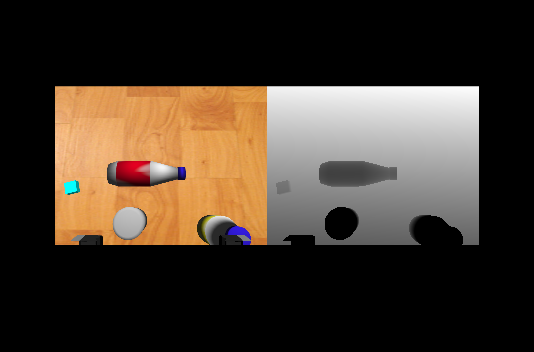

rgbImgSub = rossubscriber("/camera/rgb/image_raw","sensor_msgs/Image","DataFormat","struct");
curImage = receive(rgbImgSub,3);
pause(1)
rgbImg = rosReadImage(rgbImgSub.LatestMessage); 
rgbDptSub = rossubscriber('/camera/depth/image_raw');
curDepth = receive(rgbDptSub,3);
depthImg = readImage(rgbDptSub.LatestMessage); 
imshowpair(rgbImg,depthImg,"montage")

## **Pre-processing**

Creamos la primera máscara que retira la mesa y las cajas. Hacemos overlay para obtener la imagen sin mesa ni cajas.

imgF = rgbImg(1:450,:,:);
imgD = depthImg(1:450,:);
mask = BW_prueba01(imgF);
%imshow(mask)
justBot = imoverlay(imgF,mask,"k");
%imshow(justBot)

Creamos una segunda máscara a partir de la imagen anterior. En esta máscara usamos la depth camera para eliminar el piso que pudiese aparecer en la foto.

justBotD = imoverlay(imgD,mask,"white");
justBotD = im2gray(justBotD);
%imshow(justBotD)

%Con imbinarize
% mask = imbinarize(justBotD);
% imshow(mask)
% justBot = imoverlay(imgF,mask,"black");
% imshow(justBot)

%Con threshold
mask = justBotD > 230;
%imshow(mask)
justBot = imoverlay(imgF,mask,"black");
%imshow(justBot)

Aplicamos una operación de imclose para cerrar pequeñas areas que podrían quedar.

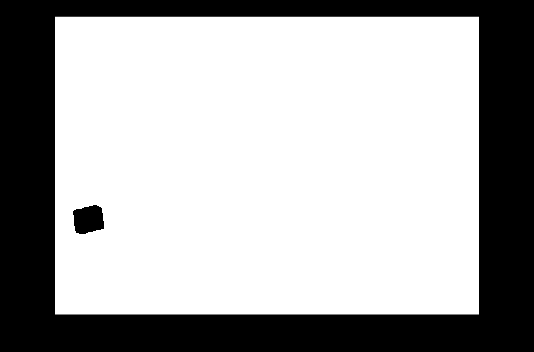

SE = strel("disk",3);
mask = imclose(mask,SE);

mask = ~bwareafilt(~mask,[1000 3000]);

justBot = imoverlay(imgF,mask,"k");
imshow(mask)

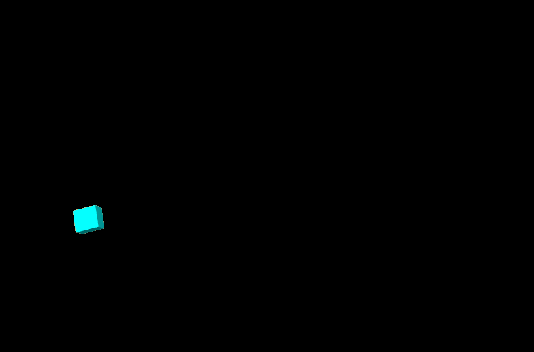

imshow(justBot)

**Get the boundaries from all the items**


stats = regionprops(~mask,"Centroid","BoundingBox")

stats = struct with fields:
       Centroid: [51.0727 307.1720]
    BoundingBox: [27.5000 285.5000 47 43]


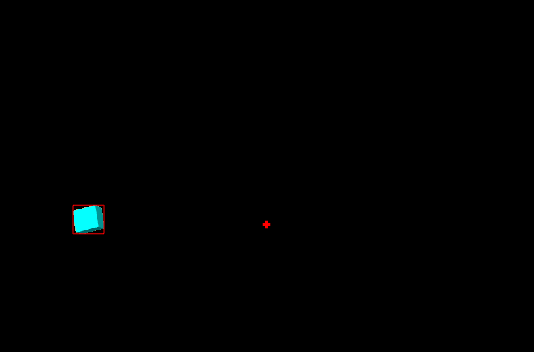


imshow(justBot)
hold on

for i = 1:size(stats,1)
    rectangle("Position",stats(i).BoundingBox,'EdgeColor','r')
end

plot(320,315, 'r+', 'MarkerSize', 5, 'LineWidth', 2);


hold off


%Gripper se alinea en el pixel [317,315]

**Obtener PointCloud**

DptPoint = rossubscriber('/camera/depth/points');
pointDepth = receive(DptPoint,3);
xyz = readXYZ(pointDepth);
%pcshow(xyz)
xyz=xyz.*[1 1 -1];
pcshow(xyz)

xyz = pointCloud(xyz)

xyz =   pointCloud with properties:

     Location: [307200×3 single]
        Count: 307200
      XLimits: [-0.3370 0.3422]
      YLimits: [-0.2565 0.2051]
      ZLimits: [-0.5938 -0.4000]
        Color: []
       Normal: []
    Intensity: []


xs = xyz.XLimits

xs = 1×2 single row vector
   -0.3370    0.3422


ys = xyz.YLimits

ys = 1×2 single row vector
   -0.2565    0.2051


%Gripper se alinea en el pixel [317,315]
clear distancias

for i = 1:size(stats,1)
    distancias(i) = sqrt((320 - stats(i).BoundingBox(1))^2 + (315-stats(i).BoundingBox(2))^2)
end

distancias = 293.9838


[~,n] = min(distancias)

n = 1


xo = xs(1) + (( 320 * (xs(2) - xs(1)))/640)

xo = single
0.0026

yo = ys(2) + (( 315 * (ys(1) - ys(2)))/480)

yo = single
-0.0978


x_n = xs(1) + (( stats(n).Centroid(1) * (xs(2) - xs(1)))/640)

x_n = single
-0.2828

y_n = ys(2) + (( stats(n).Centroid(2) * (ys(1) - ys(2)))/480)

y_n = single
-0.0903


dx = x_n - xo

dx = single
-0.2854

dy = y_n - yo

dy = single
0.0075


x = x + dy;
y = y - dx;
z = 0.3;

MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(8)

%Abrir gripper
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(4)

z = -0.04;
MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(3);

z = -0.09;
MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4);

%Cerrar gripper
OpenGripper(1.5,200,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(4)

%Levantar gripper
z = 0.3;
MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4);

%Yendo a la bascula uwu
MoveGripper(0.6,0.36,0.3,rx,ry,rz,jointMess,jointPub)

ans = logical
   1


pause(5)

%Baja poco a la bascula uwu
MoveGripper(0.6,0.36,0,rx,ry,rz,jointMess,jointPub)

ans = logical
   1


pause(5)

%Baja todo
MoveGripper(0.6,0.36,-0.03,rx,ry,rz,jointMess,jointPub)

ans = logical
   1


pause(3)

%Suelta tapa
OpenGripper(4,15,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(4)

MoveGripper(0.6,0.36,0.03,rx,ry,rz,jointMess,jointPub)

ans = logical
   1


pause(4)

MoveGripper(0.6,0.36,-0.03,rx,ry,rz,jointMess,jointPub)

ans = logical
   1


pause(4)

OpenGripper(1.5,100,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(4)

%Subimos tapa again
MoveGripper(0.6,0.36,0.3,rx,ry,rz,jointMess,jointPub)

ans = logical
   1


pause(4)

%Posición para tirar en el bote verde
MoveGripper(-0.33,0.5,0.3,rx,ry,rz,jointMess,jointPub)

ans = logical
   1


pause(4)

%Abrir gripper
OpenGripper(4,15,gripAct,gripGoal,gripperCommand)

ans = logical
   1


pause(4)

%Subimos tapa again
MoveGripper(0.6,0.36,0.3,rx,ry,rz,jointMess,jointPub)
pause(4)


## **Rutina Cubos única foto**

%Posición inicio
x = 0.826;
y = -0.033;
z = 0.3;
rx = -pi;
ry = -0.01;
rz = 0;

MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(20)


**Get image **

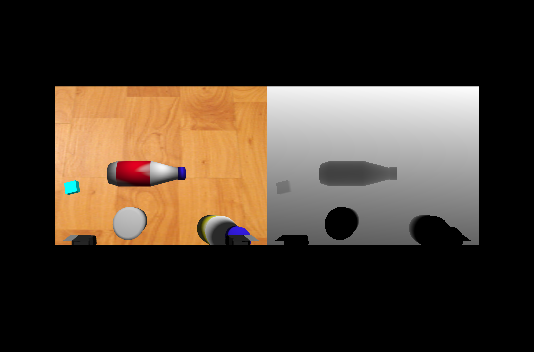

rgbImgSub = rossubscriber("/camera/rgb/image_raw","sensor_msgs/Image","DataFormat","struct");
curImage = receive(rgbImgSub,3);
pause(1)
rgbImg = rosReadImage(rgbImgSub.LatestMessage); 
rgbDptSub = rossubscriber('/camera/depth/image_raw');
curDepth = receive(rgbDptSub,3);
depthImg = readImage(rgbDptSub.LatestMessage); 
imshowpair(rgbImg,depthImg,"montage")

## **Pre-processing**

Creamos la primera máscara que retira la mesa y las cajas. Hacemos overlay para obtener la imagen sin mesa ni cajas.

imgF = rgbImg(1:450,:,:);
imgD = depthImg(1:450,:);
mask = BW_prueba01(imgF);
%imshow(mask)
justBot = imoverlay(imgF,mask,"k");
%imshow(justBot)

Creamos una segunda máscara a partir de la imagen anterior. En esta máscara usamos la depth camera para eliminar el piso que pudiese aparecer en la foto.

justBotD = imoverlay(imgD,mask,"white");
justBotD = im2gray(justBotD);
%imshow(justBotD)

%Con imbinarize
% mask = imbinarize(justBotD);
% imshow(mask)
% justBot = imoverlay(imgF,mask,"black");
% imshow(justBot)

%Con threshold
mask = justBotD > 230;
%imshow(mask)
justBot = imoverlay(imgF,mask,"black");
%imshow(justBot)

Aplicamos una operación de imclose para cerrar pequeñas areas que podrían quedar.

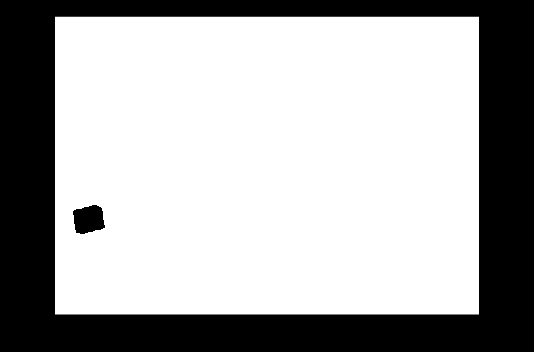

SE = strel("disk",3);
mask = imclose(mask,SE);

mask = ~bwareafilt(~mask,[1000 3000]);

justBot = imoverlay(imgF,mask,"k");
imshow(mask)

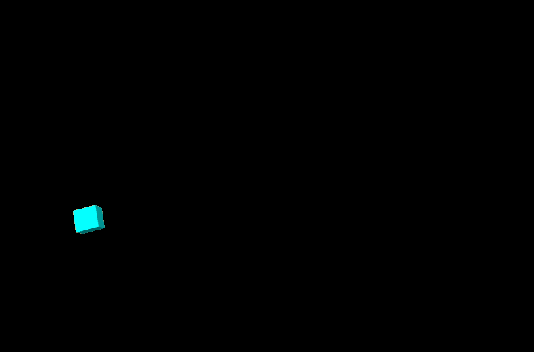

imshow(justBot)

**Get the boundaries from all the items**


stats = regionprops(~mask,"Centroid","BoundingBox")

stats = struct with fields:
       Centroid: [51.2922 307.0261]
    BoundingBox: [27.5000 285.5000 48 43]


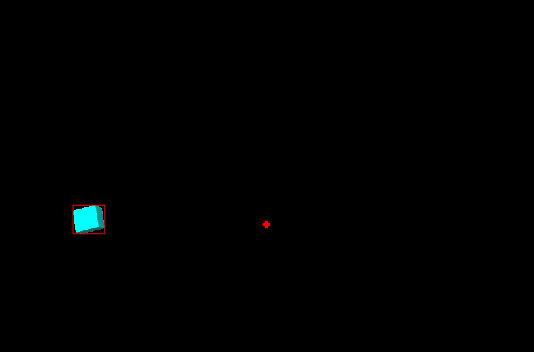


imshow(justBot)
hold on

for i = 1:size(stats,1)
    rectangle("Position",stats(i).BoundingBox,'EdgeColor','r')
end

plot(320,315, 'r+', 'MarkerSize', 5, 'LineWidth', 2);


hold off


%Gripper se alinea en el pixel [317,315]

**Obtener PointCloud**

DptPoint = rossubscriber('/camera/depth/points');
pointDepth = receive(DptPoint,3);
xyz = readXYZ(pointDepth);
%pcshow(xyz)
xyz=xyz.*[1 1 -1];
pcshow(xyz)

xyz = pointCloud(xyz)

xyz =   pointCloud with properties:

     Location: [307200×3 single]
        Count: 307200
      XLimits: [-0.3371 0.3420]
      YLimits: [-0.2564 0.2050]
      ZLimits: [-0.5935 -0.4000]
        Color: []
       Normal: []
    Intensity: []


xs = xyz.XLimits

xs = 1×2 single row vector
   -0.3371    0.3420


ys = xyz.YLimits

ys = 1×2 single row vector
   -0.2564    0.2050


**Ciclo de trabajo**

%Gripper se alinea en el pixel [317,315]
clear distancias

for i = 1:size(stats,1)
    distancias(i) = sqrt((320 - stats(i).BoundingBox(1))^2 + (315-stats(i).BoundingBox(2))^2)
end

distancias = 293.9838


d = distancias < 300

d = logical
   1



xo = xs(1) + (( 320 * (xs(2) - xs(1)))/640)

xo = single
0.0025

yo = ys(2) + (( 315 * (ys(1) - ys(2)))/480)

yo = single
-0.0978


if sum(d) > 0
    for u = 1:size(d,2)
        x = 0.626;
        y = -0.033;
        z = 0.3;
        rx = -pi;
        ry = -0.01;
        rz = 0;

        if d(u) == 1
            x_u = xs(1) + (( stats(u).Centroid(1) * (xs(2) - xs(1)))/640)
            y_u = ys(2) + (( stats(u).Centroid(2) * (ys(1) - ys(2)))/480)

            dx = x_u - xo
            dy = y_u - yo

            x = x + dy;
            y = y - dx;
            z = 0.3;

            %Alineamos a la posición de la tapa
            MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)
            pause(8)

            %Abrir gripper
            OpenGripper(4,20,gripAct,gripGoal,gripperCommand)
            pause(4)

            %Acercamos el gripper a la altura de la tapa
            z = -0.04;
            MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)
            pause(5);

            %Posicionamos el gripper
            z = -0.09;
            MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)
            pause(6);

            %Cerrar gripper
            OpenGripper(1.5,200,gripAct,gripGoal,gripperCommand)
            pause(4)

            %Levantar gripper
            z = 0.3;
            MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)
            pause(4);

            %Yendo a la bascula uwu
            MoveGripper(0.6,0.36,0.3,rx,ry,rz,jointMess,jointPub)
            pause(5)

            %Baja poco a la bascula uwu
            MoveGripper(0.6,0.36,0,rx,ry,rz,jointMess,jointPub)
            pause(5)

            %Baja todo
            MoveGripper(0.6,0.36,-0.03,rx,ry,rz,jointMess,jointPub)
            pause(3)

            %Suelta tapa
            OpenGripper(4,15,gripAct,gripGoal,gripperCommand)
            pause(4)

            %Subimos gripper
            MoveGripper(0.6,0.36,0.03,rx,ry,rz,jointMess,jointPub)
            pause(4)

            %Posicionamos gripper de nuevo
            MoveGripper(0.6,0.36,-0.03,rx,ry,rz,jointMess,jointPub)
            pause(4)

            %Cerramos gripper
            OpenGripper(1.5,100,gripAct,gripGoal,gripperCommand)
            pause(4)

            %Subimos tapa again
            MoveGripper(0.6,0.36,0.3,rx,ry,rz,jointMess,jointPub)
            pause(4)

            %Posición para tirar en el bote verde
            MoveGripper(-0.33,0.5,0.3,rx,ry,rz,jointMess,jointPub)
            pause(4)

            %Abrir gripper
            OpenGripper(4,15,gripAct,gripGoal,gripperCommand)
            pause(4)

            %Subimos tapa again
            MoveGripper(0.6,0.36,0.3,rx,ry,rz,jointMess,jointPub)
            pause(4)
        end
    end
end

x_u = single
-0.2827

y_u = single
-0.0901

dx = single
-0.2851

dy = single
0.0077

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


%Posición inicio
x = 0.826;
y = -0.033;
z = 0.3;
rx = -pi;
ry = -0.01;
rz = 0;

MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)

ans = logical
   1


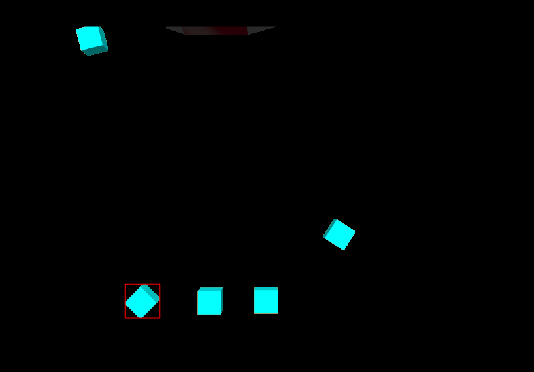

imshow(justBot)
rectangle("Position",stats(2).BoundingBox,'EdgeColor','r')

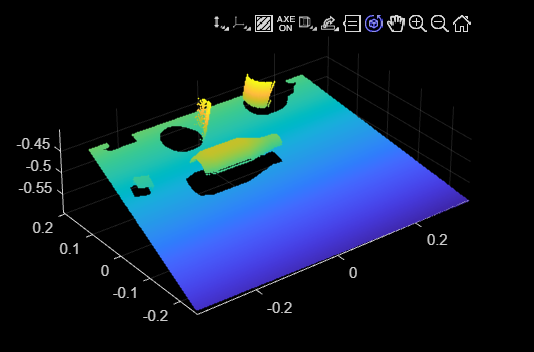

DptPoint = rossubscriber('/camera/depth/points');
pointDepth = receive(DptPoint,3);
xyz = readXYZ(pointDepth);
%pcshow(xyz)
xyz=xyz.*[1 1 -1];
pcshow(xyz)


xyz = pointCloud(xyz)

xyz =   pointCloud with properties:

     Location: [307200×3 single]
        Count: 307200
      XLimits: [-0.3371 0.3420]
      YLimits: [-0.2564 0.2050]
      ZLimits: [-0.5935 -0.4000]
        Color: []
       Normal: []
    Intensity: []


xs = xyz.XLimits

xs = 1×2 single row vector
   -0.3371    0.3420


ys = xyz.YLimits

ys = 1×2 single row vector
   -0.2564    0.2050


**Get image **

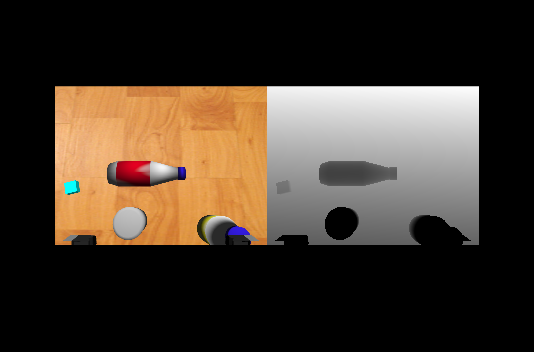

rgbImgSub = rossubscriber("/camera/rgb/image_raw","sensor_msgs/Image","DataFormat","struct");
curImage = receive(rgbImgSub,3);
pause(1)
rgbImg = rosReadImage(rgbImgSub.LatestMessage); 
rgbDptSub = rossubscriber('/camera/depth/image_raw');
curDepth = receive(rgbDptSub,3);
depthImg = readImage(rgbDptSub.LatestMessage); 
imshowpair(rgbImg,depthImg,"montage")

## **Pre-processing**

Creamos la primera máscara que retira la mesa y las cajas. Hacemos overlay para obtener la imagen sin mesa ni cajas.

imgF = rgbImg(1:450,:,:);
imgD = depthImg(1:450,:);
mask = BW_prueba01(imgF);
%imshow(mask)
justBot = imoverlay(imgF,mask,"k");
%imshow(justBot)

Creamos una segunda máscara a partir de la imagen anterior. En esta máscara usamos la depth camera para eliminar el piso que pudiese aparecer en la foto.

justBotD = imoverlay(imgD,mask,"white");
justBotD = im2gray(justBotD);
%imshow(justBotD)

%Con imbinarize
% mask = imbinarize(justBotD);
% imshow(mask)
% justBot = imoverlay(imgF,mask,"black");
% imshow(justBot)

%Con threshold
mask = justBotD > 230;
%imshow(mask)
justBot = imoverlay(imgF,mask,"black");
%imshow(justBot)

Aplicamos una operación de imclose para cerrar pequeñas areas que podrían quedar.

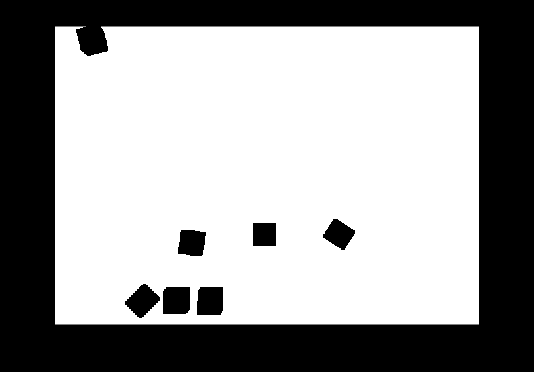

SE = strel("disk",3);
mask = imclose(mask,SE);

mask = ~bwareafilt(~mask,[1000 3000]);

justBot = imoverlay(imgF,mask,"k");
imshow(mask)

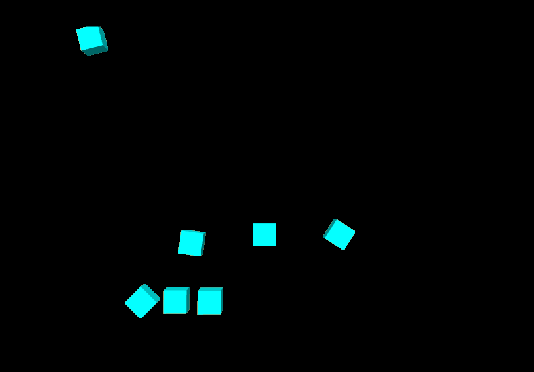

imshow(justBot)

**Get the boundaries from all the items**


stats = regionprops(~mask,"Centroid","BoundingBox")

stats = 7×1 struct array with fields:
    Centroid
    BoundingBox


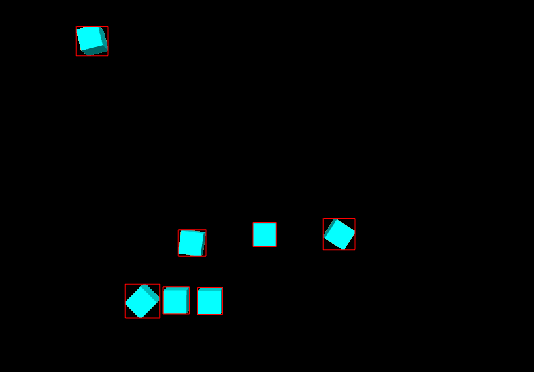


imshow(justBot)
hold on

for i = 1:size(stats,1)
    rectangle("Position",stats(i).BoundingBox,'EdgeColor','r')
end

hold off

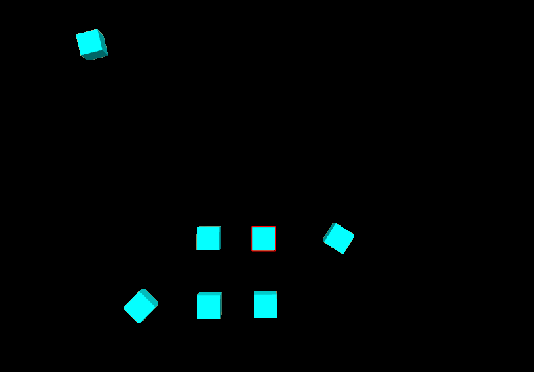


%Gripper se alinea en el pixel [317,315]

**Rutina lata roja**

%Posicionó el robot como lo anterior para asegurarme que inicie como acabó

rx = -pi;
ry = -0.01;
rz = 0;

%Posición para tirar la botella azul
MoveGripper(-0.38,-0.5,0.2,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(5)

%Soltar botella azul
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(4)

% rx = pi/2;
% ry = pi/4;
% rz = pi/2;

%Posición de inicio
%MoveGripper(-0.09,-0.68,0.18,rx,ry,rz,jointMess,jointPub)
%pause(4)

%Posición acercamiento
MoveGripper(0.025,-0.68,0.18,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)

%Posición de agarre
MoveGripper(0.025,-0.675,0.11,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)

%Agarrar lata roja
OpenGripper(0,50,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(3)

%Posición levantar
MoveGripper(0.01,-0.667,0.2,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)


**Rutina lata roja 2**

%Posicionó el robot como lo anterior para asegurarme que inicie como acabó

rx = -pi;
ry = -0.01;
rz = 0;

%Posición para tirar la botella azul
MoveGripper(-0.38,-0.5,0.25,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(5)

%Soltar botella azul
OpenGripper(4,50,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(4)

rx = -pi;
ry = pi/2 - 0.01;
rz = 0;

%Posición de inicio
%MoveGripper(-0.09,-0.66,0.18,rx,ry,rz,jointMess,jointPub)
%pause(6)

%Posición de acercamiento
MoveGripper(0.02,-0.68,0.16,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)

%Posición de agarre
MoveGripper(0.02,-0.676,0.1,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)


%Soltar botella azul
%OpenGripper(3,20,gripAct,gripGoal,gripperCommand)
frankaSLActivateGripper(0)

Gripper open...



pause(4)

%Posición de inicio
MoveGripper(0.02,-0.675,0.16,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(6)

function [done] = MoveGripper(x,y,z,rx,ry,rz,message,publisher)
gripperX = x;
gripperY = y;
gripperZ = z;

%gripperTranslation = [gripperX gripperY gripperZ];
gripperRotationX = rx; % radians
gripperRotationY = ry; % radians
gripperRotationZ = rz; % radians

message.Pose.Position.X = gripperX;
message.Pose.Position.Y = gripperY;
message.Pose.Position.Z = gripperZ;
quat = angle2quat(gripperRotationX, gripperRotationY, gripperRotationZ, "XYZ");
message.Pose.Orientation.W = quat(1);
message.Pose.Orientation.X = quat(2);
message.Pose.Orientation.Y = quat(3);
message.Pose.Orientation.Z = quat(4);
send(publisher,message);

done = true;
end

function[done] = OpenGripper(pos,force,act,goal,comando)
comando.Command.Position = pos; %0 is fully closed, 4 is fully open
comando.Command.MaxEffort = force; %N
comando.Command.Position = comando.Command.Position / 100;
goal.Command = comando.Command;
% waitForServer(act); % Can use this function if concerned with missed
% goals but generally it should work correctly.
sendGoal(act,goal)

done = true;
end
